clear all;
clc;
close all;

system=ElasticRoboticSystem();

st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'Alfa');


## Open loop

Definisco la portante come un segnale sinusoidale a bassa frequenza, con un'ampiezza tale da non sforare i limiti. L'ideale è andare in prossimità dei limiti mantenendo un discreto margine (esempio 70% limiti).

omega_portante=0.5;
ampiezza_portante=150;
T_portante=2*pi/omega_portante;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=10; %rad/s
w1=pi/st; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');
ampliezza_identificazione=400;

Sommo i due segnali

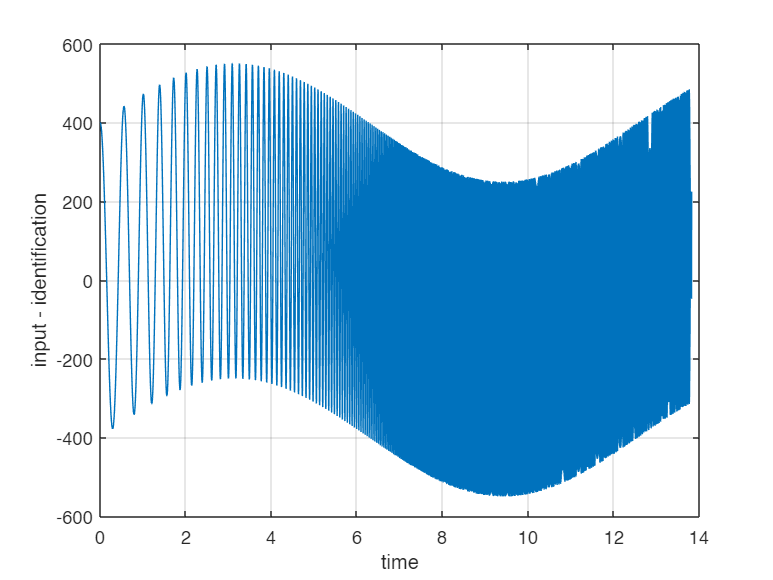

control_action=portante + control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

## Simulazione sistema

I tratti con velocità vicina allo 0 hanno una dinamica chiaramente non lineare, l'approssimazione lineare nelle frequenze esplorare dal segnale eccitante in quei punti sarà scarsa.

system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.


cs.initialize
tic
ref_j0=0;
x0=zeros(1,4);
k=50/(1/360*2*pi);
x=x0;
s=tf('s');
Ti=10;
PI=k*(1+1/(Ti*s));
pi_d=c2d(PI,st);
controller1=Controller(st,pi_d,[-600 600]);
torque=zeros(length(control_action),2);
process_output=[];
for idx=1:length(t)
    still_ca = controller1.computeControlAction(ref_j0,x(1));
    [x,t(idx,1)]=cs.openloop([still_ca control_action(idx)]);
    process_output(idx,:) = x;
    torque(idx,:) = [still_ca control_action(idx)];
end
toc

Elapsed time is 36.726225 seconds.


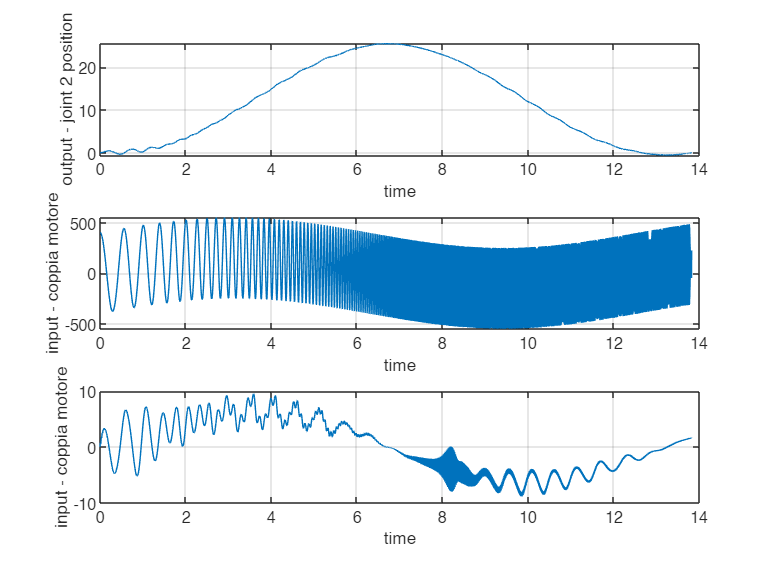


figure(1)
subplot(3,1,1)
plot(t,process_output(:,2))
xlabel('time')
ylabel('output - joint 2 position')
grid on

subplot(3,1,2)
plot(t,torque(:,2))
xlabel('time')
ylabel('input - coppia motore')
grid on

subplot(3,1,3)
plot(t,process_output(:,4))
xlabel('time')
ylabel('input - coppia motore')
grid on

% 
% figure
% subplot(2,1,1)
% plot(t,process_output(:,1))
% xlabel('time')
% ylabel('output - velocità motore')
% grid on
% 
% subplot(2,1,2)
% plot(t,torque(:,1))
% xlabel('time')
% ylabel('input - coppia motore')
% grid on

Nota: le frequenze in prossimità dei cambi di velocità sono stimate peggio (è opportuno che: 1) ripetere con segnali diversi 2) in validazione il signale sia diverso).

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(process_output(:,2),control_action,st);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);
figure(2)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

Plotto la frequenza di inizio del segnale eccitante

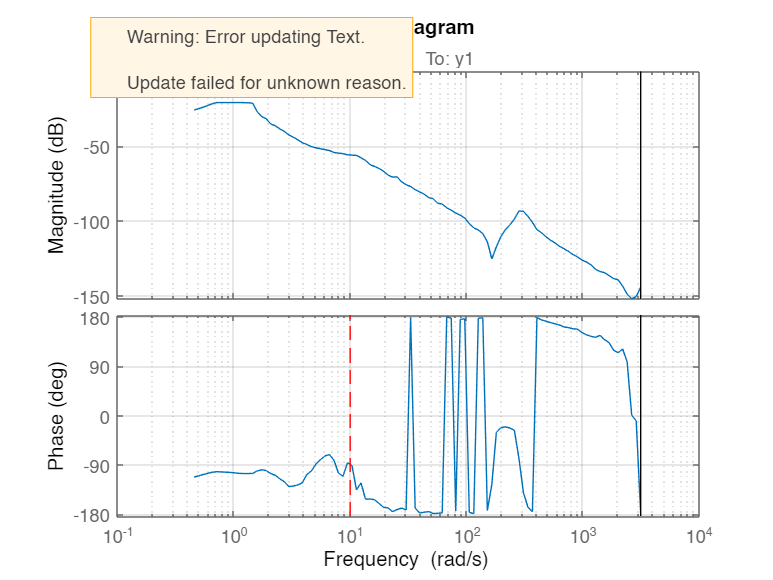

hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on

La parte a sinistra nella linea tratteggiate non mi interessa (il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico).

### Stima del modello

devo dire al modello di non considerare le basse frequenze. Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=50;
wpeso1=1000;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,4,opts);
modello_discreto = ssest(freq_resp_ident,4,'Ts',st,opts);


### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo,modello_discreto, bode_opts)

visualizzo solo il range di frequenze di interesse

xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

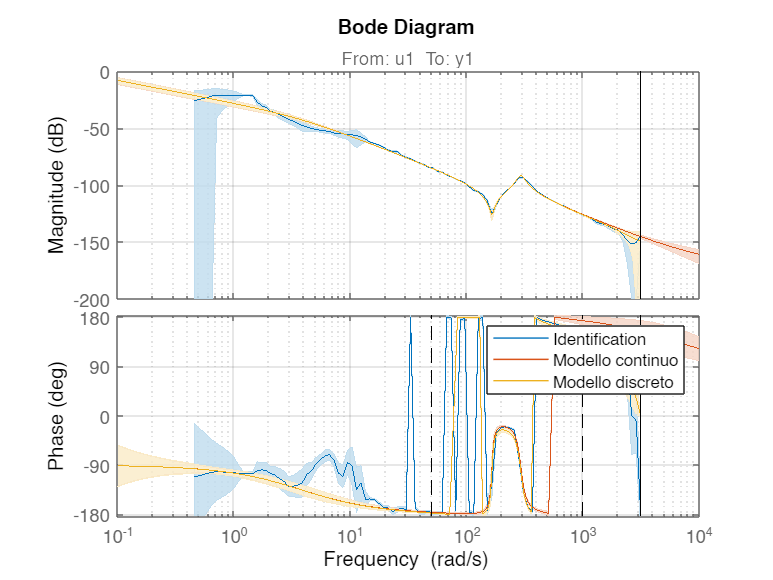

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')

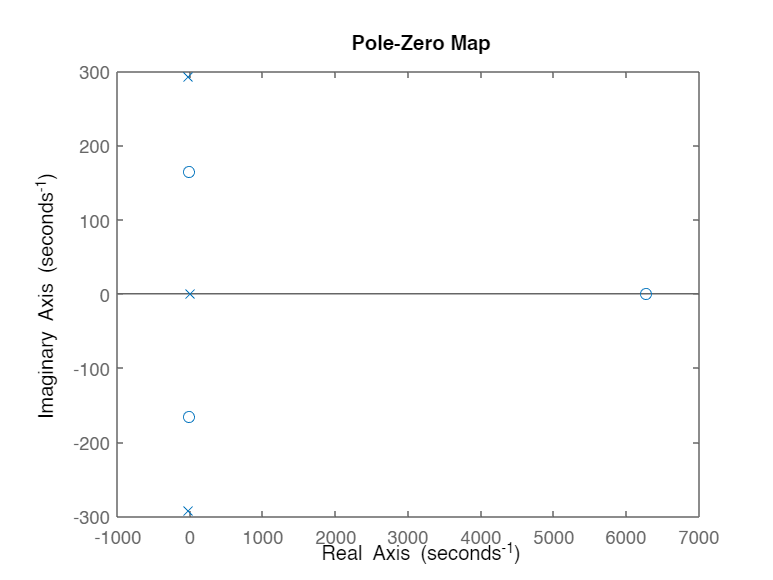

G = tf(modello_continuo);
pzmap(G)

[z,p,k] = zpkdata(G);
p=p{1,1};
index = find(real(p),3);
dominant_p = min(real(-p(index)))

dominant_p = 3.7637

tau = 1/dominant_p

tau = 0.2657

s=tf('s');